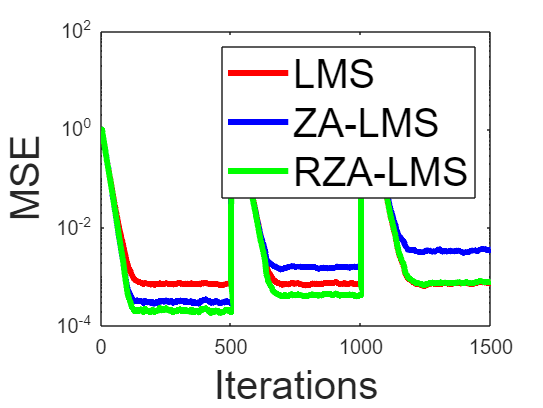

clc;
clear all;
close all;
RUNS=200;
Iterations=1500;
N=16;
u=0.05;
rho=5e-4;
eps=10;
wopt1=[zeros(1,4) -1 zeros(1,N-5)]';
wopt2=[1 0 1 0 1 0 1 0 1 0 1 0 1 0 1 0 ]';
wopt3=[1 -1 1 -1 1 -1 1 -1 1 -1 1 -1 1 -1 1 -1]';
MSE=zeros(RUNS,Iterations);
ZAMSE=zeros(RUNS,Iterations);
RZAMSE=zeros(RUNS,Iterations);
for i=1:RUNS
    wopt=wopt1;
    ws=zeros(N,1);
    wZA=zeros(N,1);
    wRZA=zeros(N,1);
    for j=1:Iterations
        if j==501
            wopt=wopt2;
            ws=zeros(N,1);
            wZA=zeros(N,1);
            wRZA=zeros(N,1);
        elseif j==1001
            wopt=wopt3;
            ws=zeros(N,1);
            wZA=zeros(N,1);
            wRZA=zeros(N,1);
        end
        
       xn(j)=randn(1,1);
       v=randn(1,1)*sqrt(0.001);
       if j<=N
       x=[flip(xn(1,1:j)) zeros(1,N-j)]';
       else
       x=[flip(xn(1,j-N+1:j)) zeros(1,N-j)]';
       end
       y=wopt'*x+v;
       e=y-(ws'*x);
       ws=ws+(u*e*x);
       MSE(i,j)=norm(wopt-ws)^2;
       e=y-(wZA'*x);
       wZA=wZA+(u*e*x)-(rho*sign(wZA));
       ZAMSE(i,j)=norm(wopt-wZA)^2;
       e=y-(wRZA'*x);
       wRZA=wRZA+(u*e*x)-((rho*sign(wRZA))./(1+eps*abs(wRZA)));
       RZAMSE(i,j)=norm(wopt-wRZA)^2;

    end
end
NMSE=sum(MSE,1)/RUNS;
ZANMSE=sum(ZAMSE,1)/RUNS;
RZANMSE=sum(RZAMSE,1)/RUNS;
semilogy(1:Iterations,NMSE,'r-',1:Iterations,ZANMSE,'b-',1:Iterations,RZANMSE,'g-',"LineWidth",3)
legend("LMS","ZA-LMS","RZA-LMS","FontSize",20)
xlabel("Iterations","FontSize",20);
ylabel("MSE","FontSize",20);